[header, signals] = load_EOG(2);

Step 1
Reading requested records. (This may take a few minutes.)...
Step 1
Reading requested records. (This may take a few minutes.)...
Step 2
Parsing data...


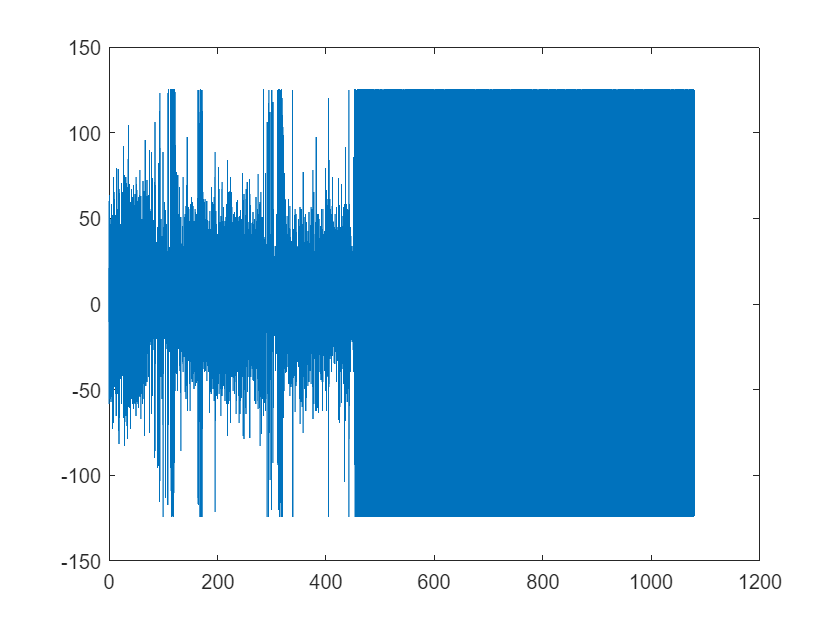


epochLen = header.samples(1) / header.duration * 30;

xs = (1:length(signals)) / epochLen;

plot(xs, signals(1, :));


measures = zeros(size(signals, 1), floor(size(signals, 2) / epochLen));

for sigNum = 1:size(signals,1)
    for epochNum = 0:(size(measures, 2) - 1)
        sigRange = (1 + epochNum * epochLen) : ((epochNum + 1) * epochLen - 1);
        measures(sigNum, epochNum + 1) = rms(signals(sigNum,sigRange));
    end
end

hold on;

isartefactArray = tabulate_artefacts_EOG(signals(1,:),50,true);

scatterColors = zeros(length(isartefactArray), 1);
%scatterColors(isartefactArray, 1) = 1.0;
scatterColors(~isartefactArray) = 1.0;

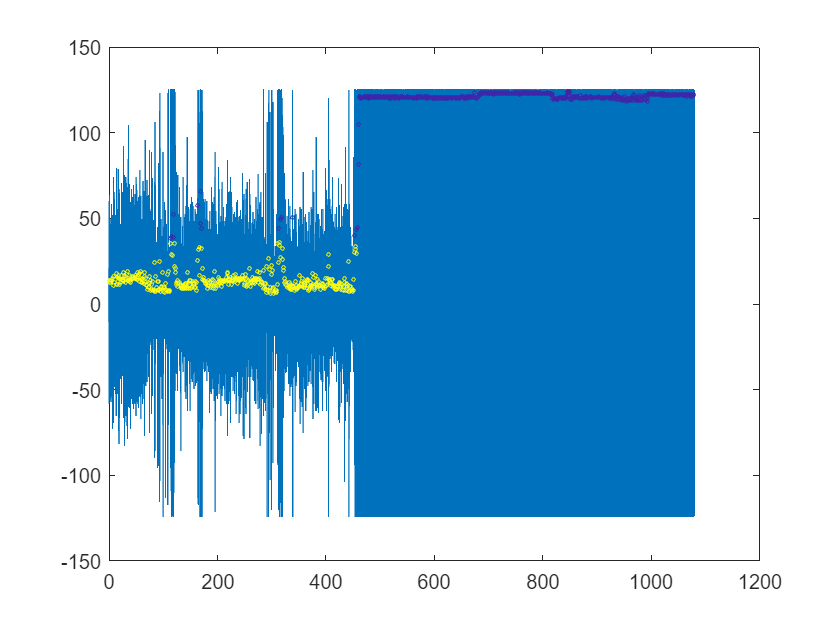


scatter(xs(1:epochLen:end), measures(1,:), 3*ones(length(measures), 1), scatterColors');